# **Commande de vol latéral**

clear all
close all
path(path,'bib1');

%  Commandes de vol laterales d'avion:
%  Données 
%

a=[ -0.1400    0.0530   -0.9990    0.0470;
   -2.4610   -0.9920    0.2620         0;
    1.5950   -0.0410   -0.2670         0;
         0    1.0000    0.0530         0];
b=[0 0.03;0.404   0.26;0.00  -0.68;0 0];
c=[ 0.0433   -0.0003    0.0016         0;...
         0    1.0000         0      0;...
         0         0    1.0000      0 ;...
         0         0         0    1.0000];
d=[0.0001   -0.0075;0 0;0 0;0 0];
plant=ss(a,b,c,d);                     % Définition du modèle d'espace d'état du système  
plant.u = {'dp','dr'};                  % Labélisation des entrée du système  
                                        % dp : deflexion des ailerons
                                        % dr : 
plant.StateName = {'beta','p','r','Phi'};
plant.y = {'ny','p','r', 'Phi'};
damp(plant)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.84e-03                 1.00e+00       3.84e-03         2.60e+02    
 -1.03e+00                 1.00e+00       1.03e+00         9.75e-01    
 -1.85e-01 + 1.33e+00i     1.38e-01       1.34e+00         5.41e+00    
 -1.85e-01 - 1.33e+00i     1.38e-01       1.34e+00         5.41e+00    


## Analyses systématiques

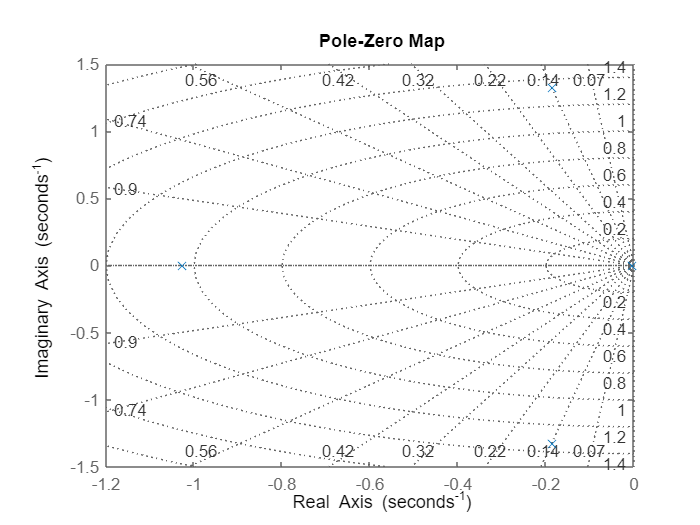

figure
pzmap(plant); grid on ;

Le tracé dans le plan complexe présente bien les trois mode du système : 

- Le mode roulis pure :  correspondant au pôle à -1,0.25

- Le mode spiral: correspondant au pôle à très proche de 0

- Le mode roulis hollandais : correspondant aux deux pôles complexes conjugués

#### Analyse avec le root square locus

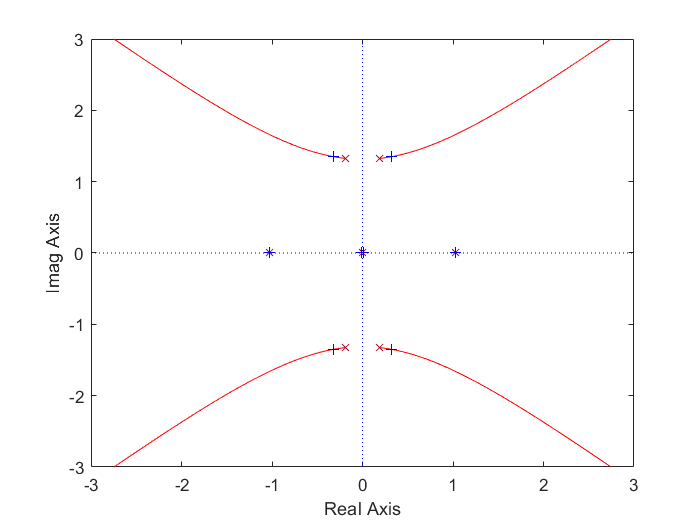

% 1- Si on ne pondère que beta
figure
rsqlocus(plant.a, plant.B, diag([1;0;0;0]),eye(2))

==> pondérer $\beta$ permet d'accelérer le rouli hollandais mais on pas d'action sur le mode spiral

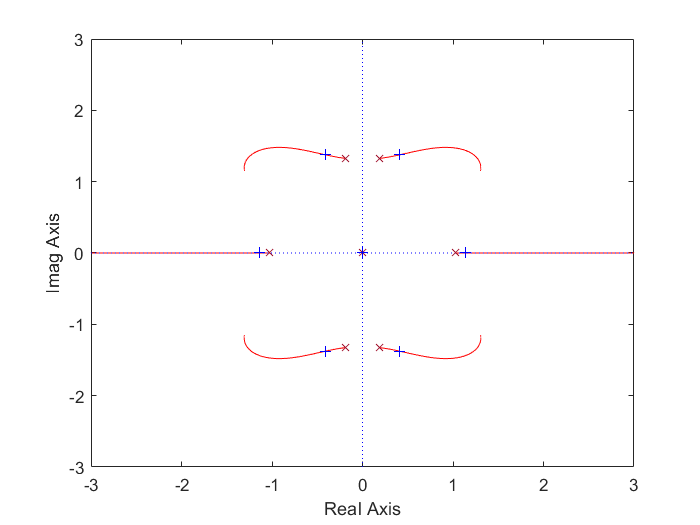

% 1- Si on ne pondère que p
figure
rsqlocus(plant.a, plant.B, diag([0;1;0;0]),eye(2))

==> pondérer $p$ permet d'accelérer efficacement le **roulis pure** mais très peu le **rouli hollandais** mais on pas d'action sur le **mode spiral**

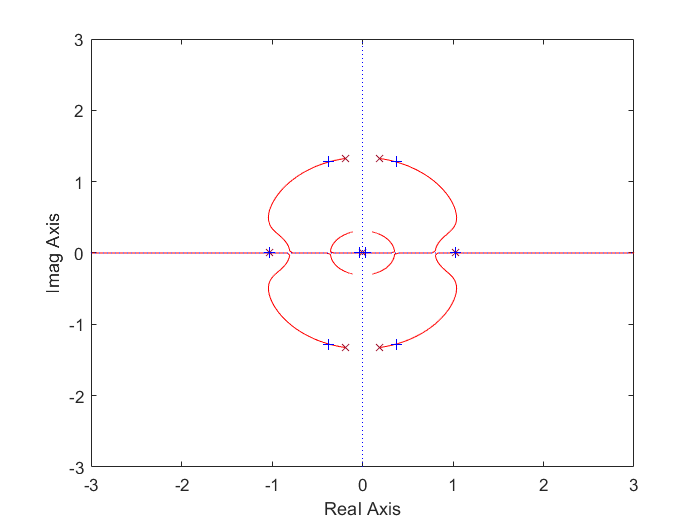

% 2- Si on ne pondère que r
figure
rsqlocus(plant.a, plant.B, diag([0;0;1;0]),eye(2))

==> pondérer $r$  permet d'amortir éfficacement le rouli hollandais

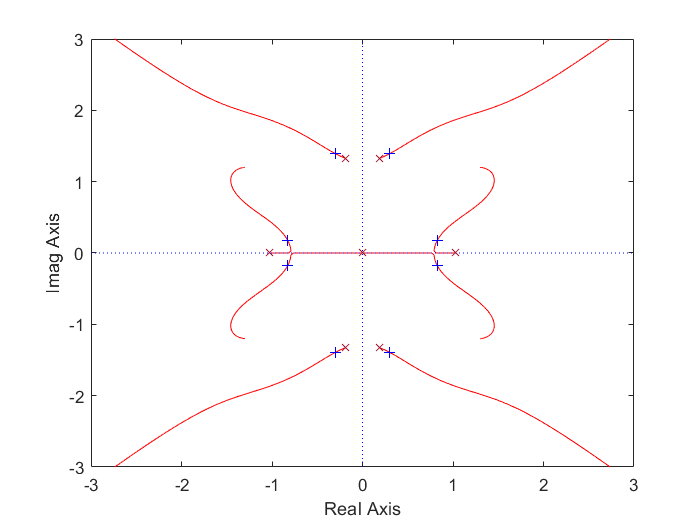


% 3- Si on ne pondère que phi
figure
rsqlocus(plant.a, plant.B, diag([0;0;0;1]),eye(2))

==> la pondération sur $\phi$ est très efficace pour accélérer le mode spiral sauf que ça ne permet pas de maitriser le découplage

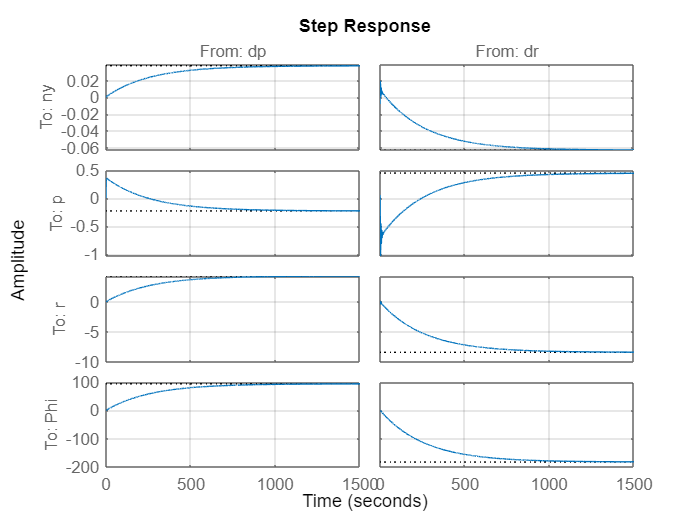

figure
step(plant); grid on 

La réponse un échelon du modèle complet montre l'influence de chacune des entrée sur les carte sortie du système

Pour cette étude on s'intéresse à deux composantes à considérer en sortie; c'est notamment :

- l'angle de dérapage ou encore l'angle de lacet $\beta \;$qui est un état du modèle 

- et l'angle de roulis $\phi$ qui est à la fois une sortie et un état du modèle 

Pour avoir $\beta$ en sortie, on va mesurer les deux états du système. 

On souhaite ensuite évaluer le couplage entre ce deux états pour cela, on simule le système en conditions initiales sur $\beta \;\textrm{et}\;\phi \;$respectivement. En utilisant la fonction ***initial*** de matlab comme suit. 

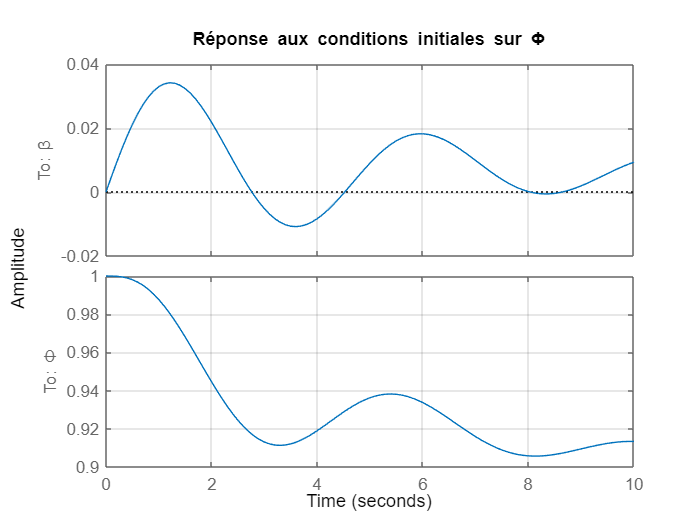

figure
syst = ss(plant.a, plant.b, [1 0 0 0; 0 0 0 1], 0);
syst.StateName = {'\beta','p','r','\Phi'};
syst.y = {'\beta', '\Phi'};
initial(syst,[0,0,0,1],10); grid on; title("Réponse aux conditions initiales sur \Phi");

On voit que la condition initial sur $\phi \;$impacte très peu $\beta$. A cause du roulis hollandais, les deux sorties sont oscillatoires 

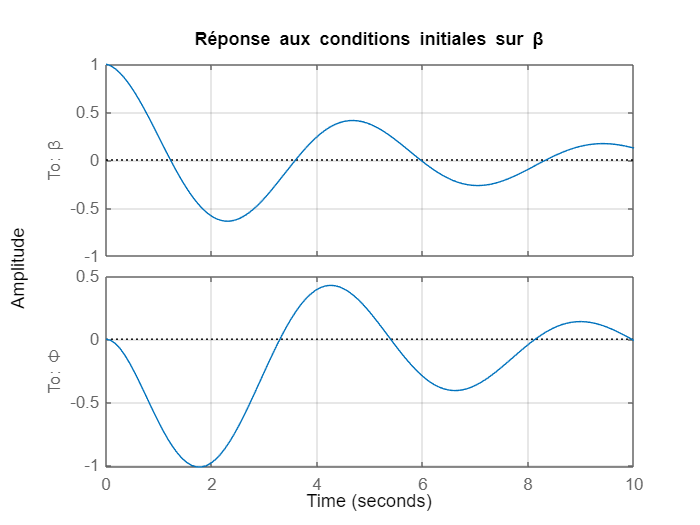

figure
initial(syst,[1,0,0,0],10); grid on; title("Réponse aux conditions initiales sur \beta");

On voit que la condition initial sur $\beta \;$impacte fortement $\phi$. A cause du roulis hollandais, les deux sorties sont oscillatoires 

## Etude en boucle ouverte du modèle

On construit le schéma simulink permettant de mesurer les états du système et d'en extraire unique ceux qui nous intéresse $\beta \;\textrm{et}\;\phi \;$ en sortie avec le vecteur de sortie y. En plus on ajoute aux entrées initiales (dp, dr) les conditions initiales de  $\beta \;\textrm{et}\;\phi$. Ce qui fait une système augmenté de 4 entrées et 6 sorties

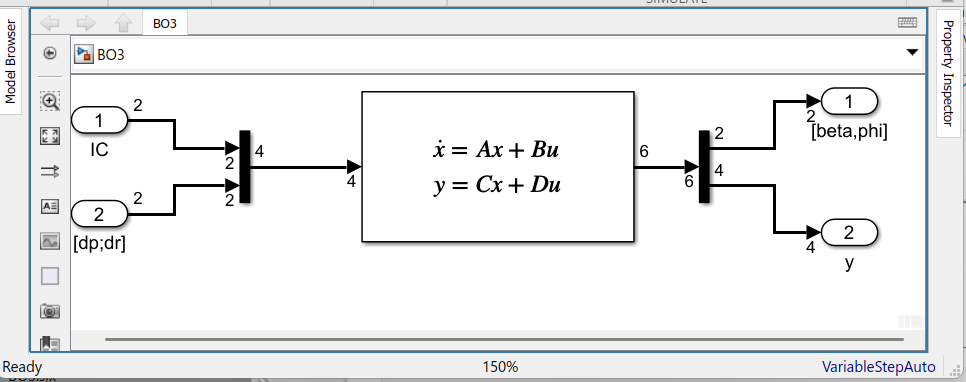

A l'aide des fonctions ***linmod ou linéarise ***des matlab on extrait les modèle en espace d'état à partir du schéma simulink

%BO3
[A, B, C, D] = linmod('BO3'); % Extraction des matrices du modèle d'état
G = ss(A,B,C, D); % Reconstruction du modèle d'état à partir des matrices
G.u = {'\beta_{initiale}', '\Phi_{initiale}','dp','dr'};          
G.StateName = {'beta','p','r','Phi'};
G.y = {'\beta', '\Phi','ny','p','r', 'Phi'};

A titre de vérification de la conformité avec l'idée du système augmenté, on ré-évalue le système aux conditions initiales cette fois avec la fonction ***impulse ***de matlab en ne récuperant que les deux premières entrées (conditions initiales de $\beta \;\textrm{et}\;\phi$) et les deux premières sortie ($\beta \;\textrm{et}\;\phi$) 

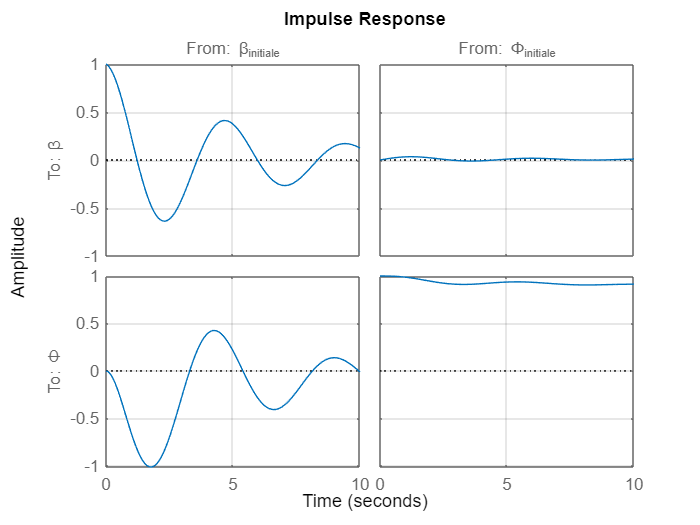

figure
impulse(G(1:2,1:2),10); grid on;

On a bien comme dans les analyses systèmatiques, la condition initiale sur $\beta$ qui influence fortement $\phi$ tandis que celle sur $\phi$ n'a qu'une très faible influence sur $\beta$. 

En plus, on a des oscillation sur les deux sortie $\beta \;\textrm{et}\;\phi$. Ces oscillations sont liées au roulis hollandais résultant du couplage entre $\beta \;\textrm{et}\;\phi$. 

## Etude en boucle fermée

### Placement de structure propre ou commande modale ou retour d'état

Dans cette partie on s'intéresse au placement d'une structure propre. 

Objectif de performance : 

- On veut placer le pôle du roulis pure à  -1,1 et découplé de $\beta$

- On veut placer le pôle du mode spiral à -1 et découplé de $\beta$

- On veut placer les pôles du mode roulis hollandais à -1+/-1,3i et découplé de $\phi$

Pour ce faire, on utilise la fonction ***place*** de matlab 

% commande modale : retour d'état 
Lda = [-1.1; -1; -1 - 1.3*sqrt(-1); -1 + 1.3*sqrt(-1)];
Kx = place(plant.a, plant.b,Lda)

Kx =    -6.1566   -1.1055    2.7227   -1.0979
   -0.9625    7.2160   -1.9123    7.1702


% verification 
eig(plant.a - plant.b*Kx)

ans =   -1.0000 + 1.3000i
  -1.0000 - 1.3000i
  -1.1000 + 0.0000i
  -1.0000 + 0.0000i


En calculant les valeurs propres du système avec retour d'état, on constate qu'ils correspondent exactement aux pôles spécitifés dans nos objectifs de performance.

#### Calcul du retour de sortie équivalent

On veut donc transformer le retour d'état en retour de sortie sachant qu'il y a une transmission directe

Trouver Ky, telque la commande $u=-K_y *y=-K_x *x$

On a $K_y =K_x *{\left(C-D*K_x \right)}^{-1}$

Ky = Kx*inv(plant.c - plant.d*Kx)

Ky =  -167.7677    7.9423    0.5393    7.9425
  -26.2268    8.6304   -2.2536    8.5835


Pour le gain de retour de sortie obtenu, on se propose d'étudie la marge de module, qui défini la distance à partir de laquelle une combinaison de gain et phase peut entrainée à la l'instabilité. Cette distance est définie par le rayon. 

#### analyse de la marge de module 

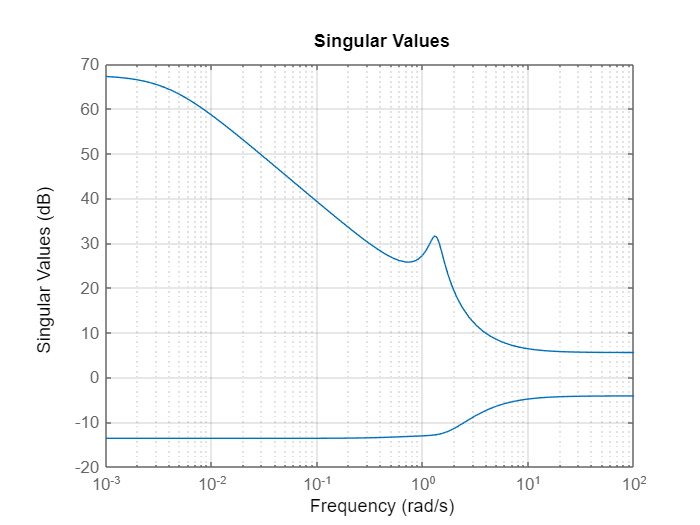

figure
sigma(eye(2) + Ky*plant); grid on; 

% marge de module
mg_mod = 1/norm(inv(eye(2) + Ky*plant), 'inf')

mg_mod = 0.2090

on a un marge de module trop faible, ce qui veut dire que pour le correcteur calculé, une petite variation combinée sur la marge de gain et celle de phase peut conduire à une instabilité.

#### Boucle fermée avec retour de sortie 

Pour construire la boucle fermée avec le retour de sortie, on utilise la fonction de lft (linear fractional transformation) qui permet d'interconnecter deux systèmes de la manière suivante : lft(sys1,sys2)

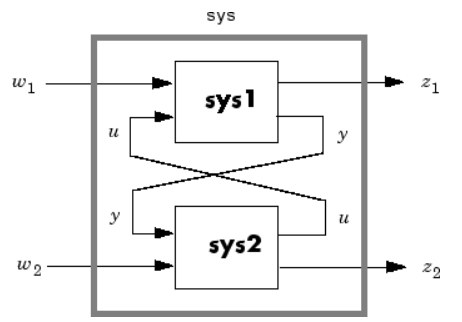

Si le nombre d'entrées/sorties du système sys2 est inférieur à celui du système sys1, w2 et z2 s'annule dans le schéma ci-dessue et on obtient un "lower LFT connection". Nous exploitons cette propriété dans notre cas pour construire notre système en boucle fermé en prenant notre système $\textrm{sys2}=-K_y$ le gain du retour de sortie.

% lft : linear fractional transformation : pour faire la boucle fermée
BF = lft(G,-Ky);
% Vérification
eig(BF) 

ans =   -1.0000 + 1.3000i
  -1.0000 - 1.3000i
  -1.1000 + 0.0000i
  -1.0000 + 0.0000i


Comme dans le cas du retour d'état, le boucle fermée avec le retour de sortie nous donne bien les pôles souhaités. 

#### Evaluation du correcteur en retour de sortie en réponse impulsionnelle

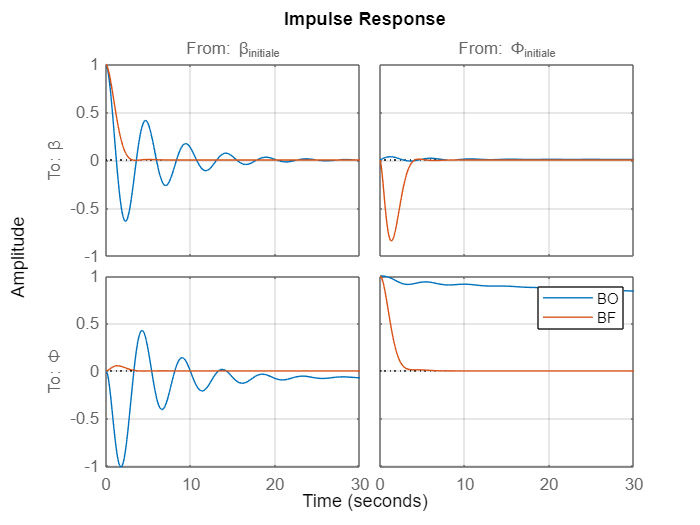

figure
impulse(G(1:2,1:2),30); grid on; hold on;
impulse(BF(1:2,1:2),30); grid on; legend("BO", "BF"); hold off; 

On vois qu'en boucle fermée  corrigée, on pu réduire fortement voir éliminer les oscillations liées au **roulis hollandais**. On a aussi accéléré le mode **spiral** lié à $\phi$ ce qui se voit très clairement sur la figure en bas à gauche de la réponse $\phi$ à $\phi _{initiale}$. 

Le retour d'état modal transformé en retour de sortie à permi de découpler, comme souhaité, le mode **spiral** de $\beta$. 

Mais un des objectif non atteint reste le découplage du **roulis hollandais** de $\phi$. Contrairement au cas de la boucle ouverte, on a la réponse de $\beta$ qui est fortement influencé par $\phi _{initiale}$. Ceci, nous informe sur la limitation du retour d'état modal et la nécessité de l'accomgner d'un mécanisme de découplage. 

#### Calcul de la précommande H ou feedforward:

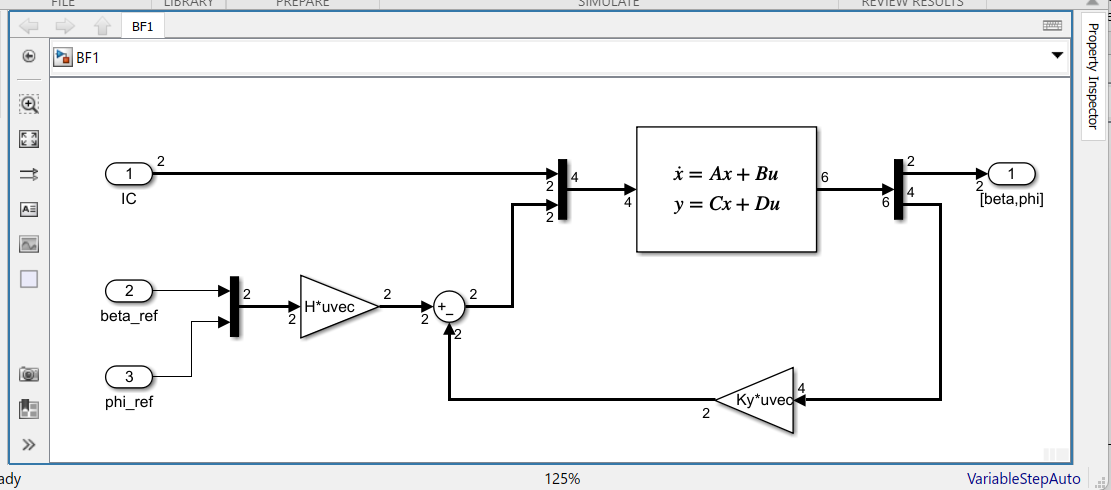

Cet gain **H** permet de définir les comportement en régime permanent comme le fait d'avoir un gain statique unitaire. 

On commence donc par l'initiliser à l'identité pour afin de pouvoir synthétiser sur simulink le modèle en boucle fermée. Puis on utilise la commande ***dcgain*** de de matlab qui nous renvoit le **gain statique** du système. Donc pour avoir un **gain statique unitaire** il suffira d'introduire en entrée de commande du système l'inverse de sont gain statique. D'où l'idée de la **précommande** $H = inv(dcgain(système))$.

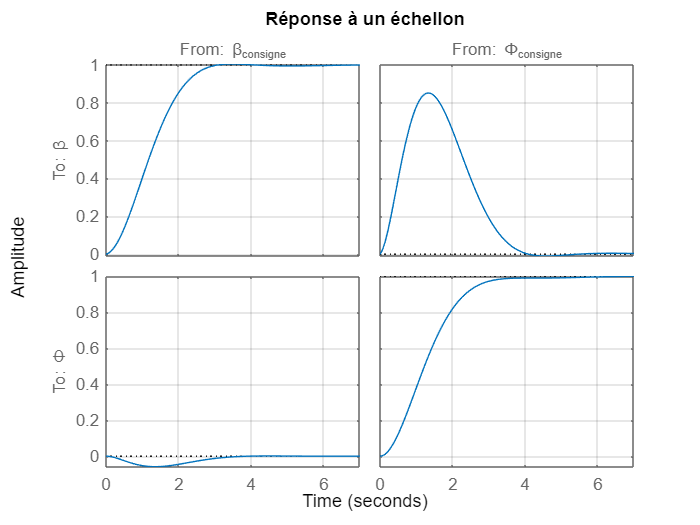

H = eye(2); 
%BF1
[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
H = inv(dcgain(Gbf(1:2,3:4)));
[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
Gbf.u = {'\beta_{initiale}', '\Phi_{initiale}','\beta_{consigne}','\Phi_{consigne}'};          
Gbf.StateName = {'beta','p','r','Phi'};
Gbf.y = {'\beta', '\Phi'};
figure
step(Gbf(1:2,3:4)); grid on; title("Réponse à un échellon")

Comme souhaité, en réponse un échellon, on trouve des réponses apériodique à **gain statique unitaire** de $\beta$ à $\beta_{consigne$ et de $\phi$ à $\phi_{consigne}$ puisque pour ces deux cas en régime permanent la sortie et la consigne sont confondu rendant l'erreur statique nulle.

Néanmoins, on peut toujours observer le problème de couplage $\beta$ à $\phi_{consigne}$ . 

### Commande modale découplante

On utilise la fonction ***null*** pour calculer le noyeau de $[A-\lambda _iI_n \ \ \  B]$ qui contient le vecteur $[v_i \ w_i]'$ 

vw1 = null([plant.a - Lda(1)*eye(4) plant.b; [1 0 0 0 0 0]]);
vw2 = null([plant.a - Lda(2)*eye(4) plant.b; [1 0 0 0 0 0]]);
vw3 = null([plant.a - Lda(3)*eye(4) plant.b; [0 0 0 1 0 0]]);
vw4 = null([plant.a - Lda(4)*eye(4) plant.b; [1 0 0 1 0 0]]);

W = [vw1(5:6) vw2(5:6) vw3(5:6) vw4(5:6)];
V = [vw1(1:4) vw2(1:4) vw3(1:4) vw4(1:4)];

#### Calcul du retour d'état découplant

on utilise la fonction "real" pour éviter d'avoir des termes complexes dans le gain du retour d'état

Kx = real(-W*inv(V)); % 
% Vérification
eig(plant.a - plant.b*Kx)

ans =   -1.0000 + 1.3000i
  -1.0000 - 1.3000i
  -1.0000 + 0.0000i
  -1.1000 + 0.0000i


Tout comme dans cas précédent on calcule le retour de sortie équivalent

Ky = Kx*inv(plant.c - plant.d*Kx)

Ky =  -157.8885    2.7227   -0.4353    2.7136
   26.0761    0.1032   -1.8651    0.0428


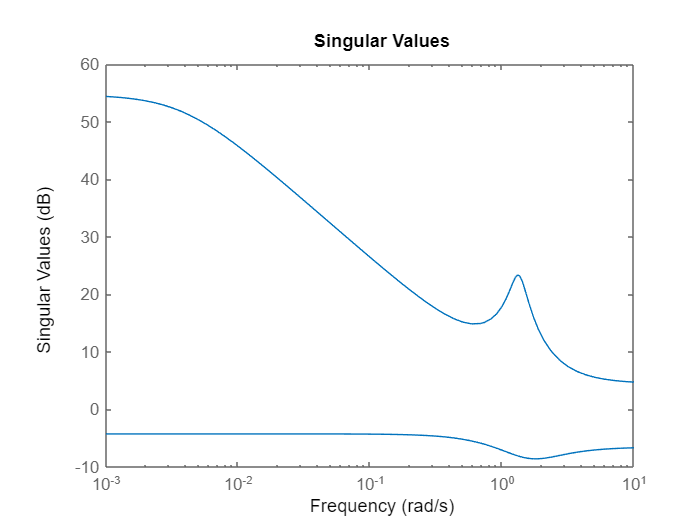

% analyse de la marge de module 
figure
sigma(eye(2) + Ky*plant)

% marge de module
mg_mod = 1/norm(inv(eye(2) + Ky*plant), 'inf')

mg_mod = 0.3722

on a un marge de module élevée par rapport à celle du retour d'état simple. Ce qui permet de conclure que le découplage améliore le domaine de stabilité en l'élargissant. 

% lft : linear fractional transformation : pour faire la boucle fermée
BF_decoupled = lft(G,-Ky);
%Verication
eig(BF_decoupled) 

ans =   -1.0000 + 1.3000i
  -1.0000 - 1.3000i
  -1.0000 + 0.0000i
  -1.1000 + 0.0000i


On re-vérifie qu'on a bien nos pôles souhaités.

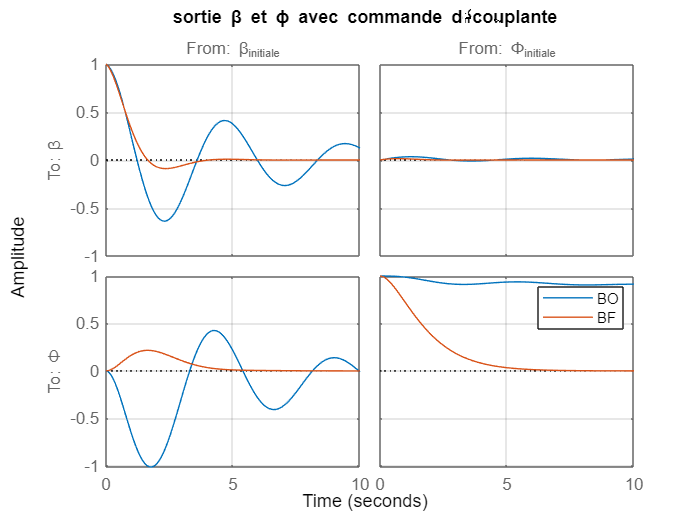

figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(BF_decoupled(1:2,1:2),10); grid on; hold off; legend("BO",'BF'); title("sortie \beta et \phi avec commande découplante")

Et cette fois-ci en réponse impulsionnelle (aux conditions initiale), on a plus de performance du retour d'état simple,  le **roulis hollandais** sur $\beta$ complètement découplé de $\phi_{initiale}$ .

#### Calcul de la précommande H ou feedforward : 

En suivant la même démarche que dans le retour d'état simple on détermine la matrice de précommande H qui assure une gain statique unitaire. 

H = eye(2);
[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
H = inv(dcgain(Gbf(1:2,3:4)))

H =     0.5754    2.6294
    3.1751   -0.0566


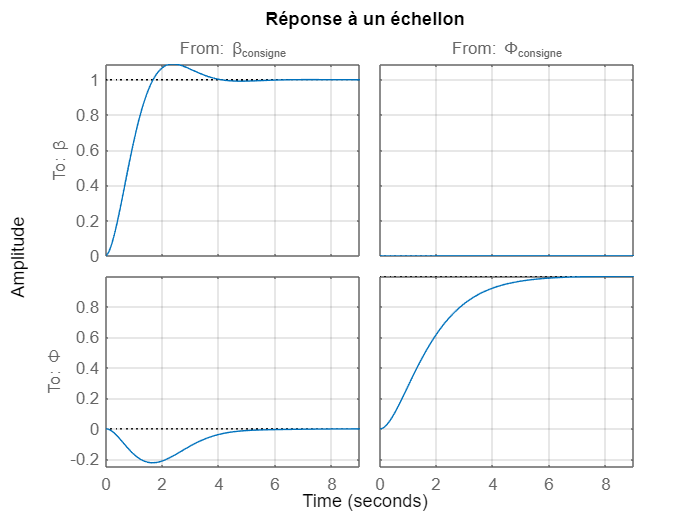

[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
Gbf.u = {'\beta_{initiale}', '\Phi_{initiale}','\beta_{consigne}','\Phi_{consigne}'};          
Gbf.StateName = {'beta','p','r','Phi'};
Gbf.y = {'\beta', '\Phi'};
figure
step(Gbf(1:2,3:4)); grid on; title("Réponse à un échellon");

Il y a un dépassement sur $\beta$ car il ne ressort que dans le roulis hollandais dont les poles sont choisis complexes en réduisant le coefficient des termes complexes pour réduire les oscillations. 

$\phi$ n'a pas de depassement car il est suramorti

#### Analyse avec le root square locus pour la commande modale découplante

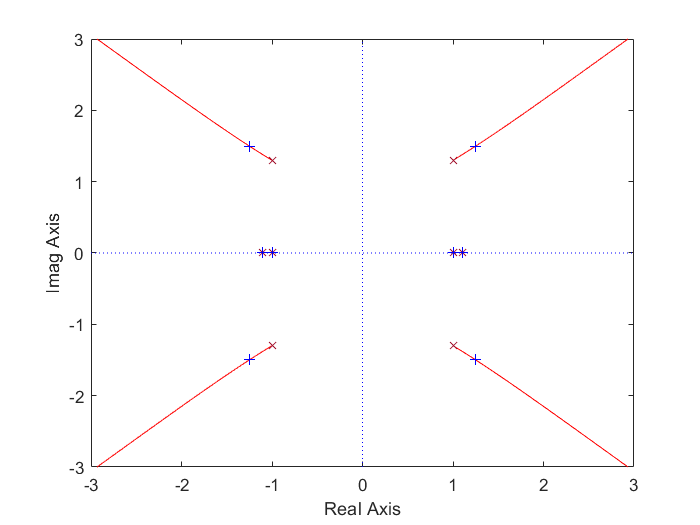

% 1- Si on ne pondère que beta
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([1;0;0;0]),eye(2))

==> pondérer $\beta$ permet d'accelérer le **rouli hollandais** mais on pas d'action ni sur le **mode spiral** ni sur le mode **roulis pur** 

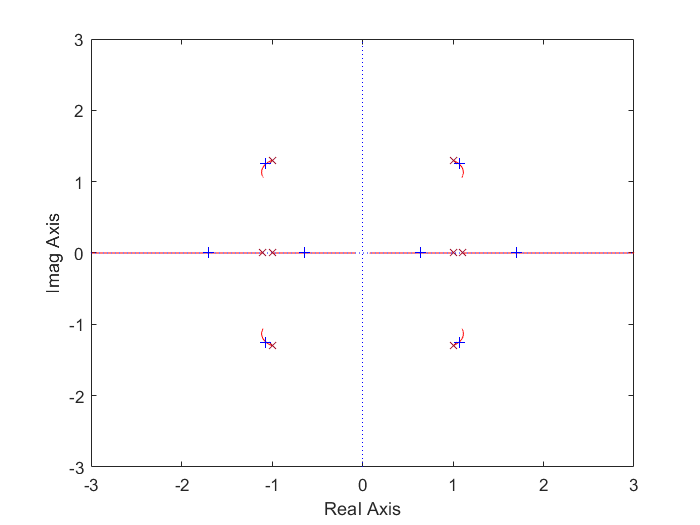

% 2- Si on ne pondère que p
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;1;0;0]),eye(2))

==> pondérer $p$ permet d'amortir très peu le **rouli hollandais, **de ralentir le **mode spiral** et d'accélérer efficacement le mode **roulis pur** 

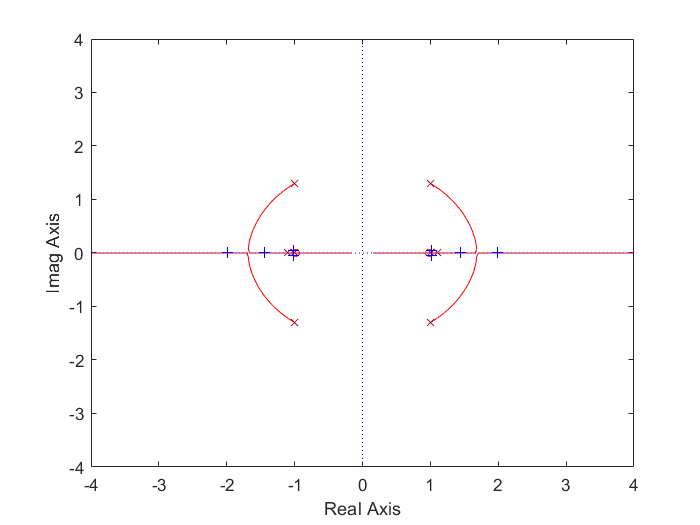

% 3- Si on ne pondère que r
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;1;0]),eye(2))

==> pondérer $r$  permet d'amortir efficacement le **rouli hollandais**, et de ralentir le mode **roulis pur **et d'avoir très peu d'action sur le mode **spiral**

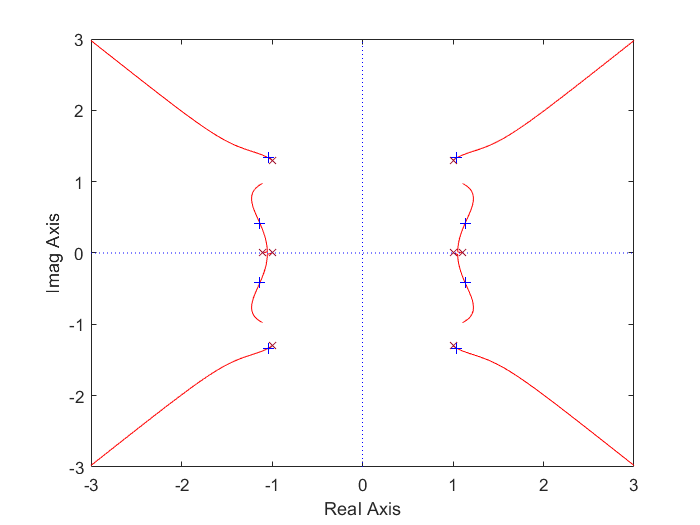

% 4- Si on ne pondère que phi
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;0;1]),eye(2))

==> la pondération sur $\phi$ est très efficace pour accélérer le **roulis hollandais** et permet de mal amortir les modes **spiral et roulis pur**

## Commande LQ

### Commande LQ classique 

L'idée de cette commande est de trouver un retour d'état permettant des stabiliser le système tout en minimisant l'indice de performance quadratique .

On cherchera donc à trouver un compromis entre le niveau de performance et le sollicitation de la commande nécessaire.

Pour le critère 

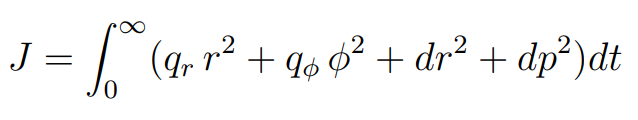

Le objectifs de performances qu'on se fixe ici sont : 

- d'avoir facteur d'amortissement d'au moins $0.6$ 

- et d'avoir le mode spiral accélé et plus plus rapide que $1 rad/s$

On procède par essai erreur en faisant vérier les deux terme du la matrice $Q_x$ contenu dans le critère notamment $q_r$ et $q_{\phi}$ qui sont les seuls degrés de libertés, la matrice $R$ étant fixé à l'identité.

qr = 1;
qphi = 1;
Qx = diag([0 0 qr qphi]);
R = eye(2);
[Kx,S,CLP] = lqr(plant, Qx,R);
damp(CLP)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -4.24e-01 + 1.34e+00i     3.01e-01       1.41e+00          2.36e+00    
 -4.24e-01 - 1.34e+00i     3.01e-01       1.41e+00          2.36e+00    
 -8.33e-01 + 1.86e-01i     9.76e-01       8.54e-01          1.20e+00    
 -8.33e-01 - 1.86e-01i     9.76e-01       8.54e-01          1.20e+00    


Objectifs de performance non atteints donc, on readapte nos paramètres.

#### Calcul du retour d'état  

qr = 10;
qphi = 4;
Qx = diag([0 0 qr qphi]);
R = eye(2);
[Kx,S,CLP] = lqr(plant, Qx,R);
damp(CLP)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -8.35e-01 + 9.86e-01i     6.46e-01       1.29e+00          1.20e+00    
 -8.35e-01 - 9.86e-01i     6.46e-01       1.29e+00          1.20e+00    
 -1.25e+00 + 4.18e-01i     9.48e-01       1.32e+00          8.00e-01    
 -1.25e+00 - 4.18e-01i     9.48e-01       1.32e+00          8.00e-01    


On atteint bien nos objectif de performance. On peut aussi constaté que l'on a que deux modes. Le deux premiers pôles correspondent au **roulis hollandais**  alors que les deux derniers correspondent la fusion des modes **spiral et roulis pur**

#### Calcul du retour de sortie équivalent

Ky = Kx*inv(plant.c - plant.d*Kx)

Ky =   -26.7425    0.8912    0.1702    1.3665
   28.2244   -0.6853   -2.9633   -0.8100


#### analyse de la marge de module 

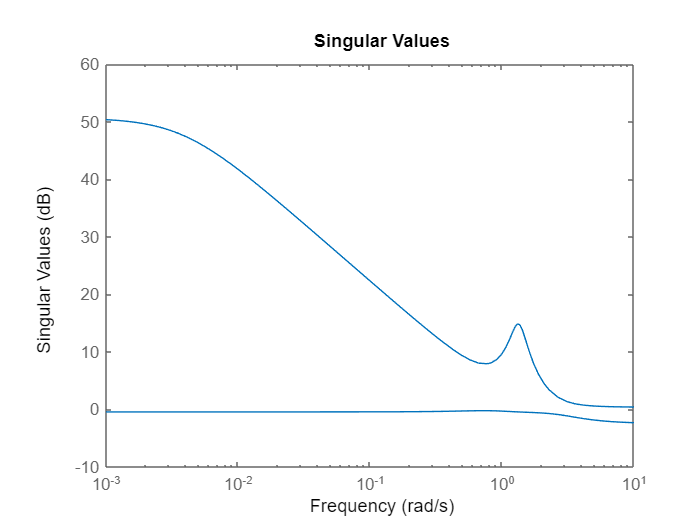

figure
sigma(eye(2) + Ky*plant)

% marge de module
mg_mod = 1/norm(inv(eye(2) + Ky*plant), 'inf')

mg_mod = 0.7525

on a un marge de module est beaucoup mieux, offrant un grand domaine de gain stabilisant pour le système.

% lft : linear fractionnar transformation : pour faire la boucle fermée
BF_LQ = lft(G,-Ky);
%Verication
eig(BF_LQ)

ans =   -0.8352 + 0.9857i
  -0.8352 - 0.9857i
  -1.2505 + 0.4179i
  -1.2505 - 0.4179i


#### Visualisation et conclusion

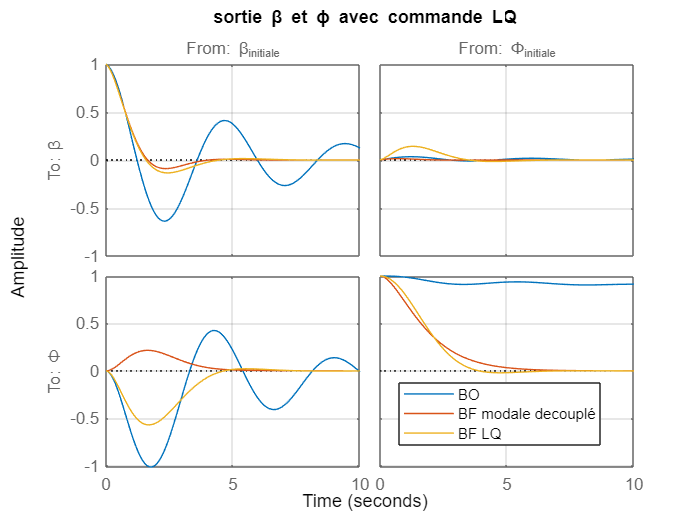

figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(BF_decoupled(1:2,1:2),10);
impulse(BF_LQ(1:2,1:2),10); grid on; hold off; legend("BO","BF modale decouplé",'BF LQ'); title("sortie \beta et \phi avec commande LQ")

On constate maintenant que le **roulis hollandais** est bien amortie comme mon peut les voir plus clairement sur $\beta$ qui n'est plus oscillatoire. Le mode **spiral** bien accélé. Même si le découplage n'était pas défini comme objectif de performance on constate tout de même qu'il a été fait mais il reste moins bien comparé au **retour d'état découplant**. 

#### Calcul de la précommande H:

H = eye(2);
% BF1
[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
H = inv(dcgain(Gbf(1:2,3:4)))

H =     3.9184    1.3421
    3.3033   -0.9579


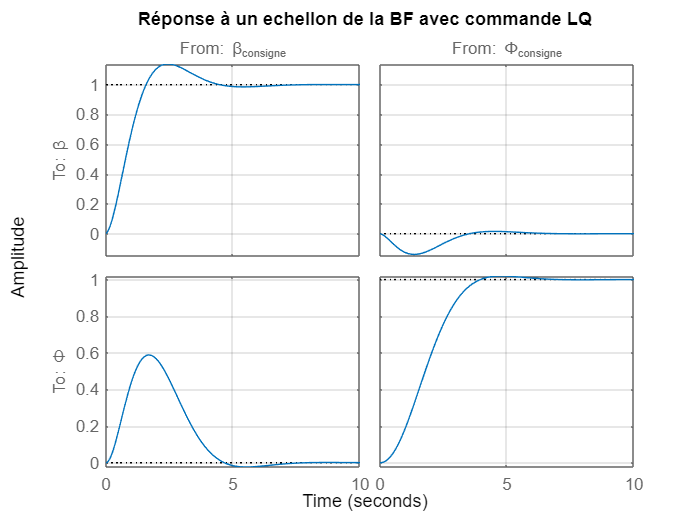

[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
Gbf.u = {'\beta_{initiale}', '\Phi_{initiale}','\beta_{consigne}','\Phi_{consigne}'};          
Gbf.StateName = {'beta','p','r','Phi'};
Gbf.y = {'\beta', '\Phi'};
figure
step(Gbf(1:2,3:4)); grid on; title("Réponse à un echellon de la BF avec commande LQ")

Réponse échellon, on a un gain statique unitaire, mais un couplage non négligeable du mode **spiral, **lié à $\phi$ , à $\beta_{consigne}$. 

#### Analyse avec le root square locus pour la commande LQ classique

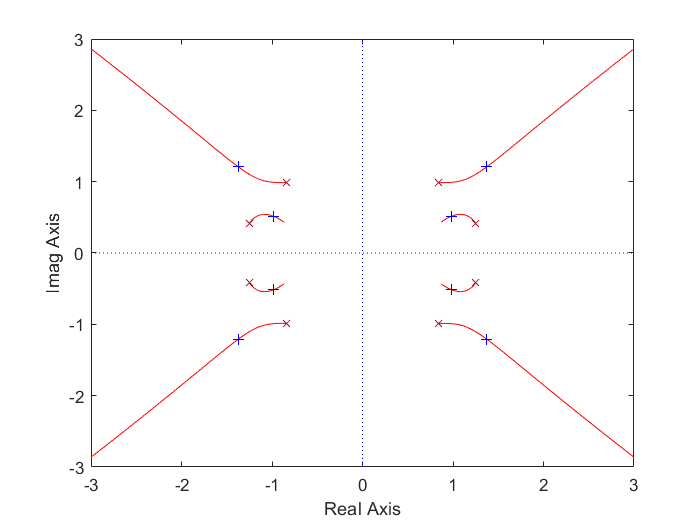

% 1- Si on ne pondère que beta
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([1;0;0;0]),eye(2))

==> pondérer $\beta$ permet d'accelérer le **roulis hollandais** mais on ralentit légèrement le mode équilavent** spiral** et **roulis pur** 

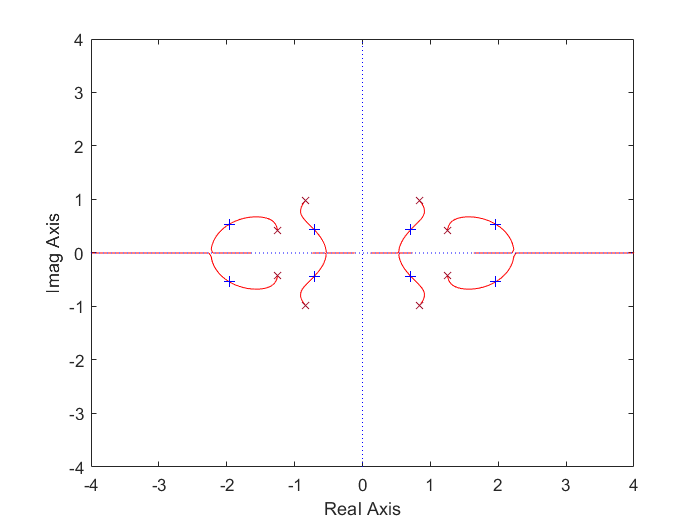

% 2- Si on ne pondère que p
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;1;0;0]),eye(2))

==> pondérer $p$ permet d'amortir le **rouli hollandais, **d'accélérer et d'amortir le mode équilavent** spiral** et **roulis pur** 

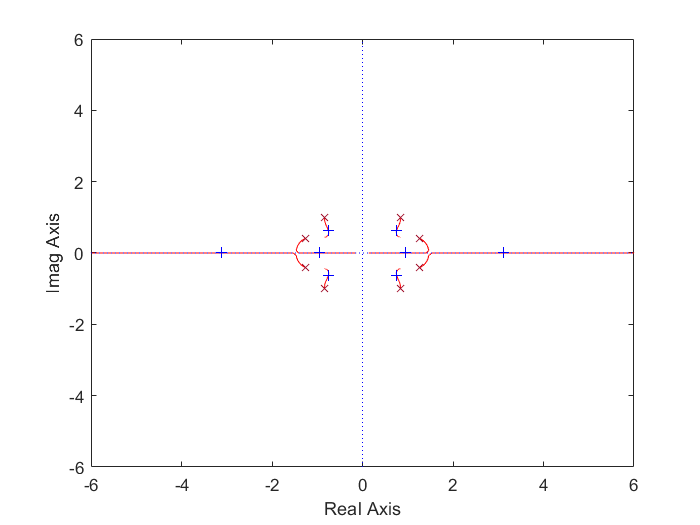

% 3- Si on ne pondère que r
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;1;0]),eye(2))

==> pondérer $r$  permet d'amortir légèrement le **roulis hollandais**, d'amortir le mode équilavent** spiral** et **roulis pur** et d'accélérer (respective de ralentir) les pôle de ce dernier de partie imaginaire négative ( respectivement positive). 

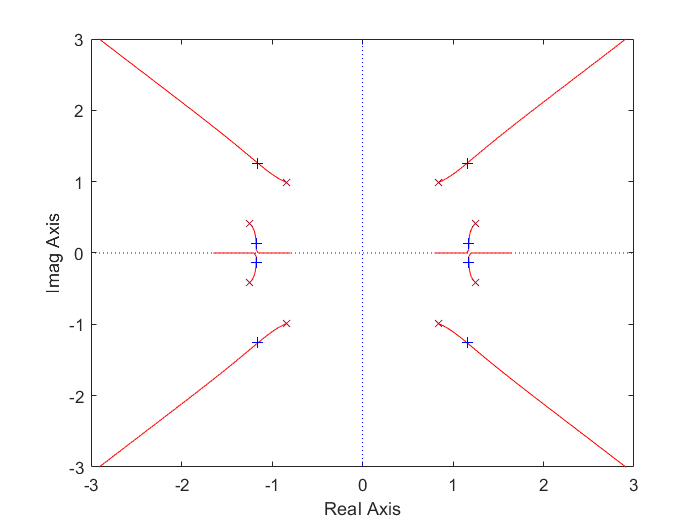

% 4- Si on ne pondère que phi
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;0;1]),eye(2))

==> la pondération sur $\phi$ est très efficace pour accélérer le **roulis hollandais** et d'amortir le mode équilavent** spiral** et **roulis pur** et d'accélérer (respective de ralentir) les pôle de ce dernier de partie imaginaire négative ( respectivement positive). 

### Modèle implicite de référence ou Implicit reference model : IRM

On est toujour dans l'idée de la synthèse LQ mais cette fois le gain de retour d'état est synthétisé avec un modèle de référence

xir = 1.001; wr = 1.049;
xil = 0.61; wl = 1.64;

Ad = [0 0 -1 0; 0 -2*xir*wr 0 -wr^2; wl^2 0 -2*xil*wl 0; 0 1 0 0];
damp(Ad)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.00e+00 + 1.30e+00i     6.10e-01       1.64e+00          1.00e+00    
 -1.00e+00 - 1.30e+00i     6.10e-01       1.64e+00          1.00e+00    
 -1.10e+00                 1.00e+00       1.10e+00          9.12e-01    
 -1.00e+00                 1.00e+00       1.00e+00          9.97e-01    


Qx = (plant.a - Ad)'*(plant.a - Ad); 

[Kx,S,CLP] = lqr(plant, Qx, plant.b'*plant.b, (plant.a -Ad)'*plant.b);
damp(CLP)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.01e+00                 1.00e+00       1.01e+00          9.93e-01    
 -1.09e+00                 1.00e+00       1.09e+00          9.17e-01    
 -1.10e+00 + 1.29e+00i     6.49e-01       1.69e+00          9.11e-01    
 -1.10e+00 - 1.29e+00i     6.49e-01       1.69e+00          9.11e-01    


#### Calcul du retour de sortie équivalent

Ky = Kx*inv(plant.c - plant.d*Kx)

Ky =  -127.2194    2.6915    0.0350    2.6914
   28.6590    0.0639   -2.0429    0.0080


#### analyse de la marge de module 

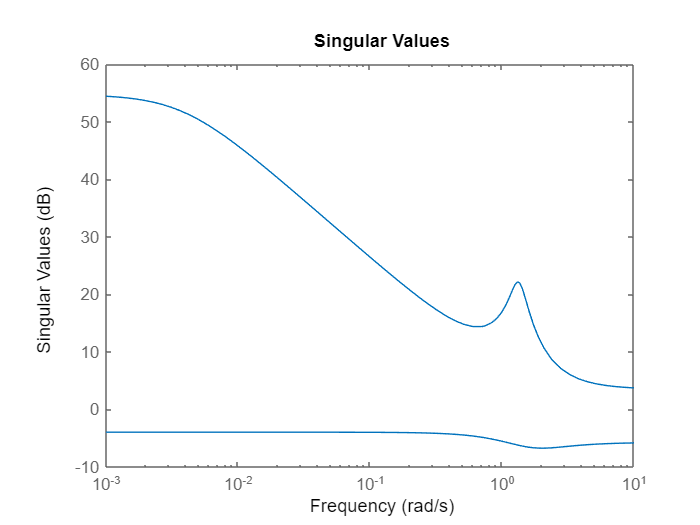

figure
sigma(eye(2) + Ky*plant)

% marge de module
mg_mod = 1/norm(inv(eye(2) + Ky*plant), 'inf')

mg_mod = 0.4607

on a un marge de module est mieux

% lft : linear fractionnar transformation : pour faire la boucle fermée
BF = lft(G,-Ky);
%Verication
eig(BF)

ans =   -1.0973 + 1.2867i
  -1.0973 - 1.2867i
  -1.0067 + 0.0000i
  -1.0904 + 0.0000i


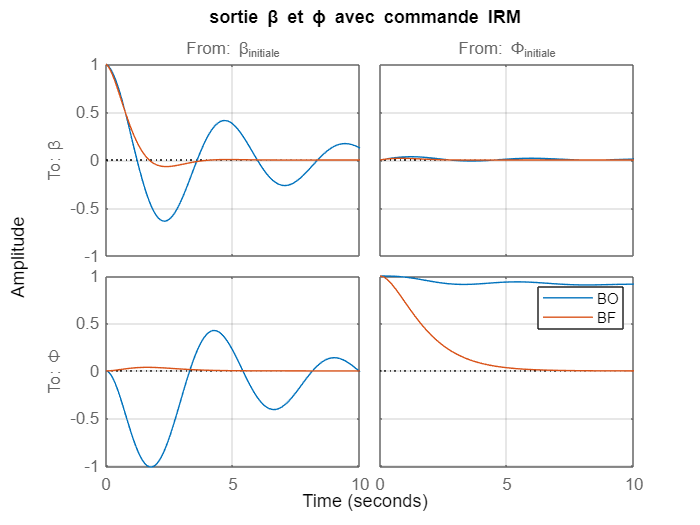

figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(BF(1:2,1:2),10); grid on; hold off; legend("BO",'BF'); title("sortie \beta et \phi avec commande IRM")

#### Calcul de la précommande H:

H = eye(2);
%BF1
[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
H = inv(dcgain(Gbf(1:2,3:4)))

H =     1.3361    2.6355
    3.2540   -0.0990


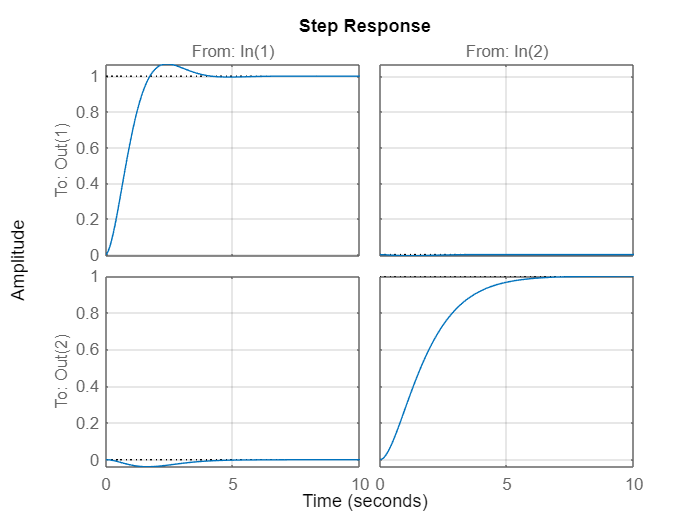

[A, B, C, D] = linmod('BF1');
Gbf = ss(A,B,C,D);
figure
step(Gbf(1:2,3:4)); grid on; 

#### Analyse avec le root square locus pour la commande LQ classique

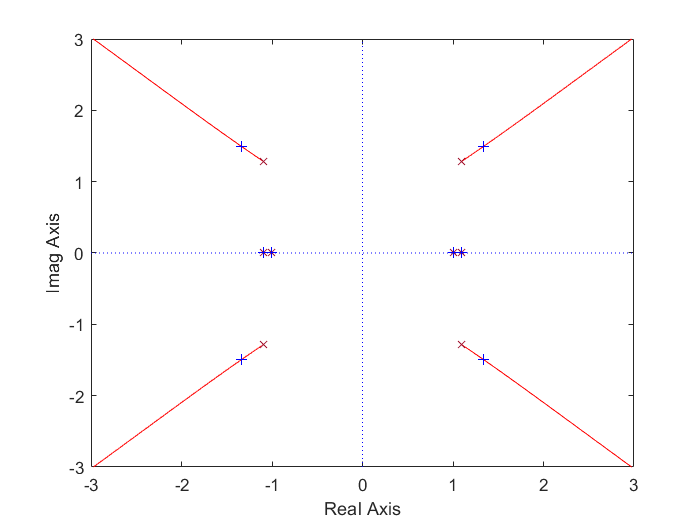

% 1- Si on ne pondère que beta
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([1;0;0;0]),eye(2))

==> pondérer $\beta$ permet d'accelérer efficacement le **roulis hollandais** mais on a pas d'action sur les modes** spiral** et **roulis pur** 

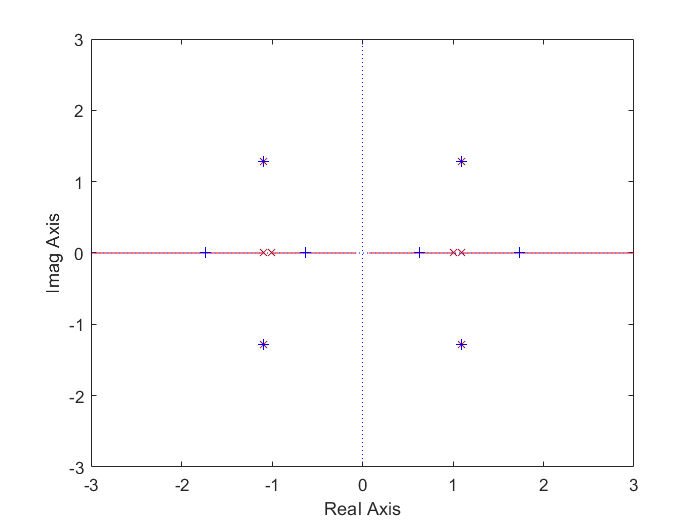

% 2- Si on ne pondère que p
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;1;0;0]),eye(2))

==> pondérer $p$ permet d'accélérer le mode **roulis pur, **de ralentir de mode **spiral** mais n'a pas d'action sur le **rouli hollandais**

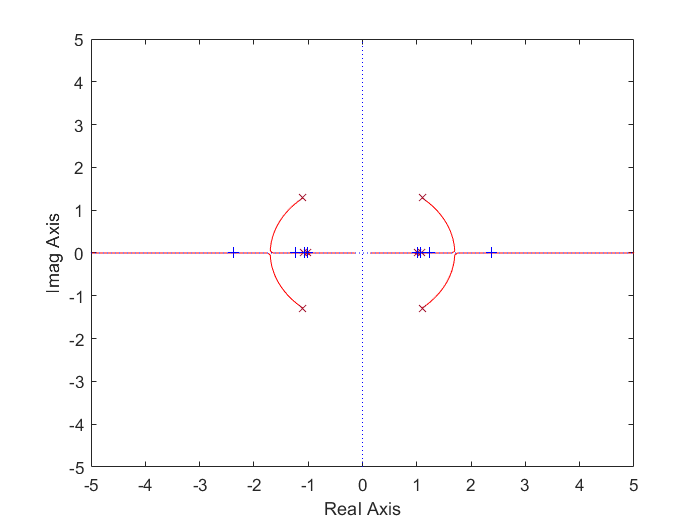

% 3- Si on ne pondère que r
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;1;0]),eye(2))

==> pondérer $r$  d'amortir le mode **roulis hollandais **et d'accélérer (respective de ralentir) les pôle de ce dernier de partie imaginaire négative ( respectivement positive), mais n'a aucune incidence sur les mode **spiral** et **roulis pur**

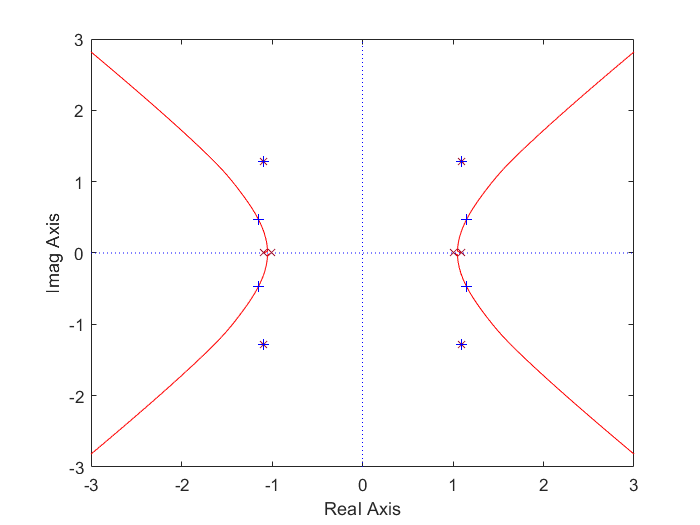

% 4- Si on ne pondère que phi
figure
rsqlocus(Gbf.A, Gbf.B(:,3:4), diag([0;0;0;1]),eye(2))

==> la pondération sur $\phi$ n'a pas d'action sur le mode **roulis hollandais** et de mal amortir les modes** spiral** et **roulis pur** en les accélérant. 

## Synthèse $H_{\infty }$

Le problème de système de correcteur pose et se résout comme un problème d'optimisation.

### Synthèse $H_{\infty }$ ordre plein

#### Définition des filtres de pondération 

num_f1 = [wl*wl];
den_f1 = [1 2*xil*wl wl*wl];
F1 = tf(num_f1,den_f1)

F1 =
 
          2.69
  --------------------
  s^2 + 2.001 s + 2.69
 
Continuous-time transfer function.



num_f2 = [wr*wr];
den_f2 = [1 2*xir*wr wr*wr];
F2 = tf(num_f2,den_f2)

F2 =
 
         1.1
  -----------------
  s^2 + 2.1 s + 1.1
 
Continuous-time transfer function.



#### Le problème standard de commande:

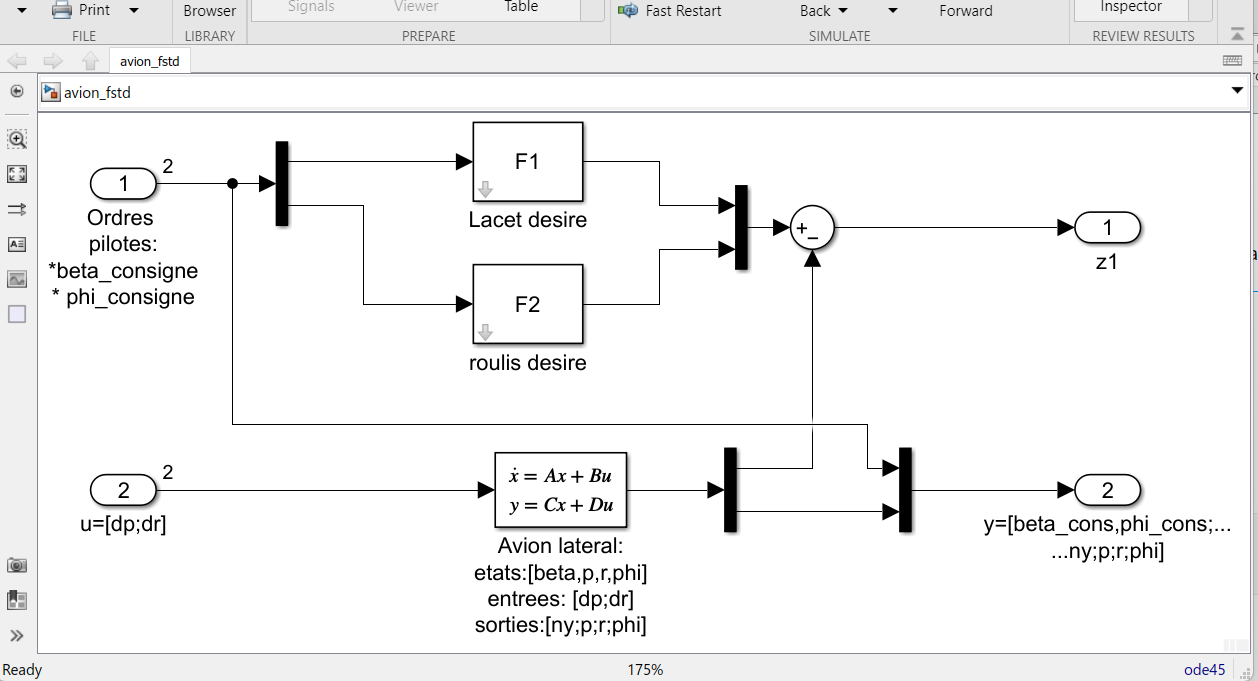

P = linearize("avion_fstd");
[K, CLopt, gamma] = hinfsyn(P,6,2);
size(K)

State-space model with 2 outputs, 6 inputs, and 8 states.


damp(K)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00                 1.00e+00       1.00e+00         9.97e-01    
 -1.10e+00                 1.00e+00       1.10e+00         9.12e-01    
 -1.00e+00 + 1.30e+00i     6.10e-01       1.64e+00         1.00e+00    
 -1.00e+00 - 1.30e+00i     6.10e-01       1.64e+00         1.00e+00    
 -2.29e+01                 1.00e+00       2.29e+01         4.36e-02    
 -4.58e+02 + 4.27e+02i     7.31e-01       6.26e+02         2.19e-03    
 -4.58e+02 - 4.27e+02i     7.31e-01       6.26e+02         2.19e-03    
 -7.44e+03                 1.00e+00       7.44e+03         1.34e-04    


gamma 

gamma = 2.7464e-06

le **gamma** représente ici l'erreur de suivi : Il est assez faible ce qui informe sur la performance en terme de précision du contrôleur obtenu

Le problème avec de correcteur est que ces poles sont trop difficile à implémenter : -7444 par exemple

#### analyse de la marge de module 

on ne prend que le retour de sortie avec un signe moins sur le K car on a pas de retour négatif de base avec la norme H infinie

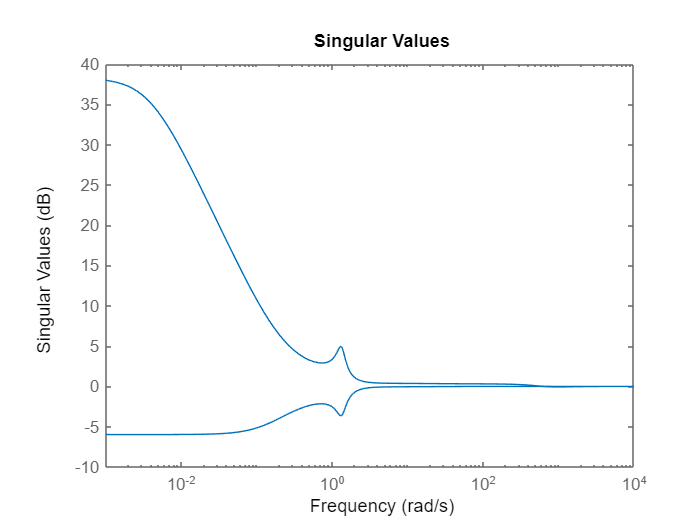

figure
sigma(eye(2) - K(:,3:6)*plant) 

% marge de module
mg_mod = 1/norm(inv(eye(2) - K(:,3:6)*plant), 'inf')

mg_mod = 0.5026

on a un marge de module est beaucoup mieux

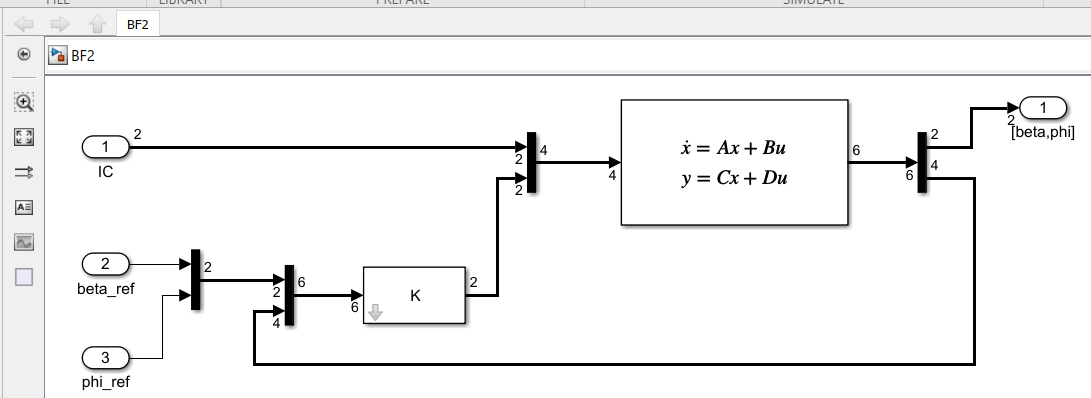

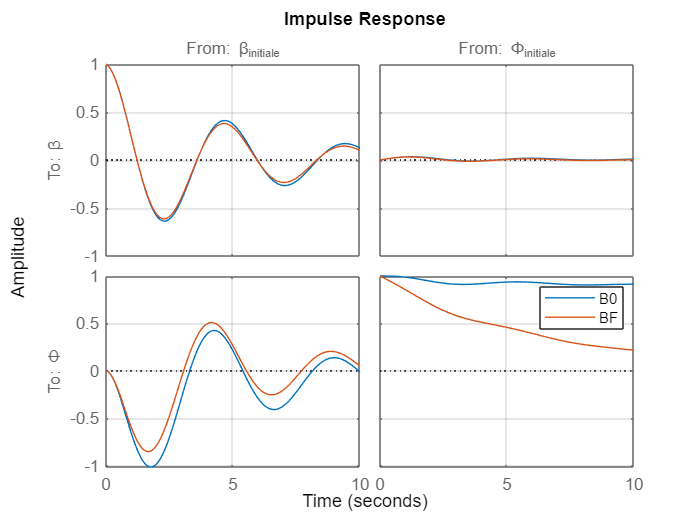

% BF2
[A, B, C, D] = linmod('BF2');
Gbf2 = ss(A,B,C,D);
Gbf2.u = {'\beta_{initiale}', '\Phi_{initiale}','\beta_{consigne}','\Phi_{consigne}'};          
Gbf2.y = {'\beta', '\Phi'};

figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(Gbf2(1:2,1:2), 10); grid on; legend("B0", "BF");hold off;

Cette solution marche très bien en suivi de consigne mais pas en réponse à des conditions initiales car le couplage reste aussi important qu'en boucle ouverte.

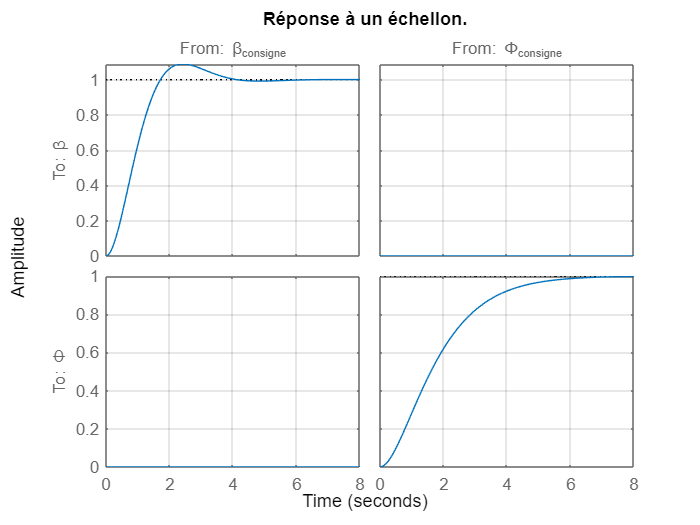

figure
step(Gbf2(1:2,3:4)); grid on; title("Réponse à un échellon.")

Contrairement à la réponse aux conditions initiale on a pas de couplage et surtourt on des grain statique unitaire ce qui confirme la performance du correcteur en suivi de consigne.

### Synthèse $H_{\infty }$ du controleur statique K0

 tunableGain:  permet d'ajouté une variable de décision 

K0 = tunableGain('Control', 2, 6)

K0 =   Tunable gain "Control" with 2 outputs, 6 inputs, and 12 tunable parameters.

Type "ss(K0)" to see the current value and "get(K0)" to see all properties.


%  système en boucle fermée : CL(P,K)
CL0 = lft(P,K0);
CL0.u = {'beta_ref', 'phi_ref'};
CL0.y = {'err_beta', 'err_phi'};

On va maintenant définir les objectifs

Req = TuningGoal.Gain(CL0.u, CL0.y, 1)

Req =   Gain with properties:

          MaxGain: [1×1 zpk]
            Focus: [0 Inf]
        Stabilize: 1
     InputScaling: []
    OutputScaling: []
            Input: {2×1 cell}
           Output: {2×1 cell}
           Models: NaN
         Openings: {0×1 cell}
             Name: ''


On va utiliser systune

[CLopt, fBest] = systune(CL0, Req);

Final: Soft = 0.028, Hard = -Inf, Iterations = 111


soft correspond à à l'erreur de suivi gamma. 

Iterations indique le nombre d'itération passées à la recherche de l'optimum. 

Kopt = getValue(K0,CLopt)

Kopt =
 
  D = 
             u1        u2        u3        u4        u5        u6
   y1     1.385     2.971     124.5      -3.4   -0.3171    -2.935
   y2     3.018  -0.06192     -20.5  -0.09448     1.764  -0.03516
 
Name: Control
Static gain.



Un Kopt est un gain statique, donc uniquement une transmission directe; c'est pour cela qu'il ne contient que la matrice D

#### Marge de module

on ne prend que le retour de sortie avec un signe moins sur le K car on a pas de retour négatif de base avec la norme H infinie

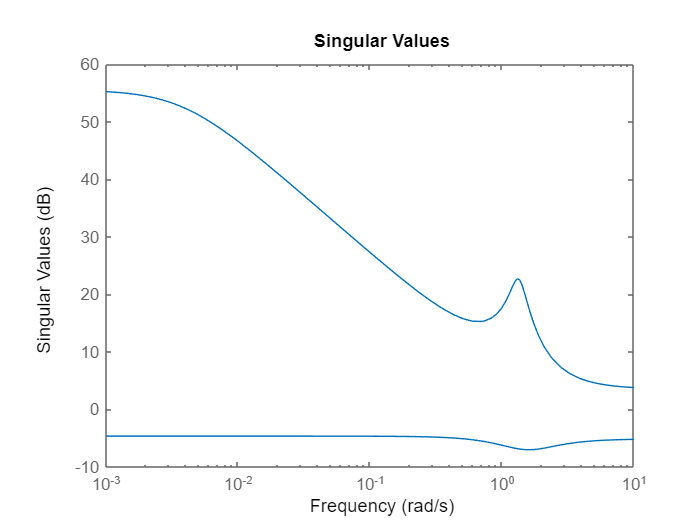

figure
sigma(eye(2) - Kopt(:,3:6)*plant)

% marge de module
mg_mod = 1/norm(inv(eye(2) - Kopt(:,3:6)*plant), 'inf')

mg_mod = 0.4466

on a un marge de module est beaucoup mieux

K = Kopt

K =
 
  D = 
             u1        u2        u3        u4        u5        u6
   y1     1.385     2.971     124.5      -3.4   -0.3171    -2.935
   y2     3.018  -0.06192     -20.5  -0.09448     1.764  -0.03516
 
Name: Control
Static gain.



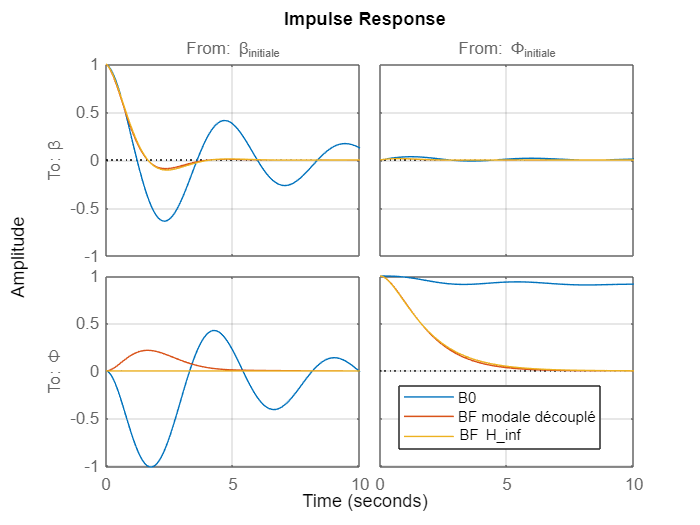

% BF2
[A, B, C, D] = linmod('BF2');
Gbf2 = ss(A,B,C,D);
figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(BF_decoupled(1:2,1:2),10); grid on;
impulse(Gbf2(1:2,1:2), 10); grid on; legend("B0","BF modale découplé", "BF H_{inf}");hold off;

La synthèse $H_{\infty }$ du contrôleur statique permet d'avoir un découplage parfait même bien meilleur que la commande modale découplante, comblant ainsi l'insuffisance de la synthèse $H_{\infty }$ pleine ordre

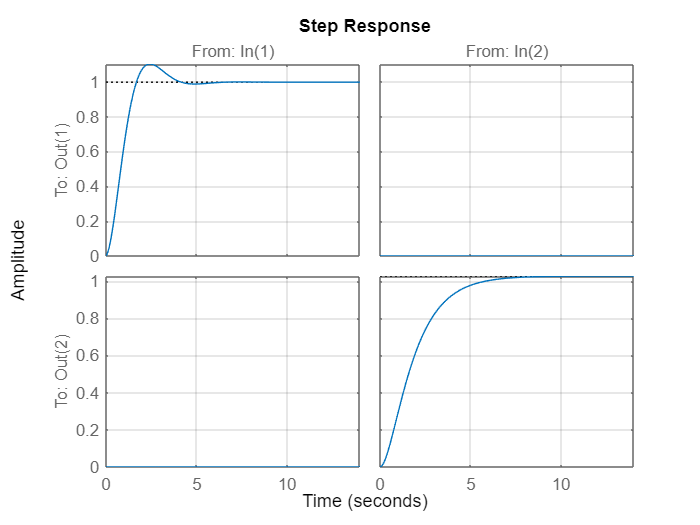

figure
step(Gbf2(1:2,3:4)); grid on; 

Ce correcteur est à la fois performant en suivi de consigne et en réponse aux conditions initiales

### Utilisation du random start

systuneOption : permet de paramétrer la méthode de résolution du problème. 

Ici nous souhaitons que la recherche l'optimum se fasse avec plusieurs initialisation de sort à explorer à divers endroit du domaine de recherche afin de maximiser les chances d'avoir l'optimum global. 

opt = systuneOptions;
opt.RandomStart = 3;
[CLopt, fBest] = systune(CL0, Req, [], opt)

Final: Soft = 0.028, Hard = -Inf, Iterations = 111
Final: Soft = 0.185, Hard = -Inf, Iterations = 197
Final: Soft = 0.028, Hard = -Inf, Iterations = 113
Final: Soft = 0.028, Hard = -Inf, Iterations = 95

CLopt =

  Generalized continuous-time state-space model with 2 outputs, 2 inputs, 8 states, and the following blocks:
    Control: Tunable 2x6 gain, 1 occurrences.

Type "ss(CLopt)" to see the current value, "get(CLopt)" to see all properties, and "CLopt.Blocks" to interact with the blocks.



fBest = 0.0280

Au bout de quelques initialisations, l'algorime finit par converger vers le même optimum que précédamment. Cela reconforte sur le fait d'être à l'optimum global.

Kopt = getValue(K0,CLopt)

Kopt =
 
  D = 
             u1        u2        u3        u4        u5        u6
   y1     1.385     2.971     124.5      -3.4   -0.3171    -2.935
   y2     3.018  -0.06192     -20.5  -0.09448     1.764  -0.03516
 
Name: Control
Static gain.



### Synthèse multi-objectif:

On cherche à mémoriser le modèle de référence sur $\beta$

On cherche à mémoriser le modèle de référence sur $\phi$

sans se soucier du couplage

Req1 = TuningGoal.Gain('beta_ref','err_beta', 1);
Req2 = TuningGoal.Gain('phi_ref','err_phi',1);
[CLopt, fBest] = systune(CL0, Req1, Req2);
Kopt = getValue(K0,CLopt)

Un Kopt est un gain statique, donc uniquement une transmission directe; c'est pour cela qu'il ne contient que la matrice D

% Marge de module
figure
sigma(eye(2) - Kopt(:,3:6)*plant) % on ne prend que le retour de sortie avec un signe moins sur le K car on a pas de retour négatif de base avec la norme H infinie
% marge de module

Final: Soft = 1.03e-10, Hard = 0.19574, Iterations = 147


mg_mod = 1/norm(inv(eye(2) - Kopt(:,3:6)*plant), 'inf')

Kopt =
 
  D = 
            u1       u2       u3       u4       u5       u6
   y1    26.62    21.25    1.044   -40.28   -38.84   -19.19
   y2  0.02801    -3.02   -10.52    6.005     8.09    2.301
 
Name: Control
Static gain.



on a un marge de module est bien mieux que dans le cas précédent en mono objectif

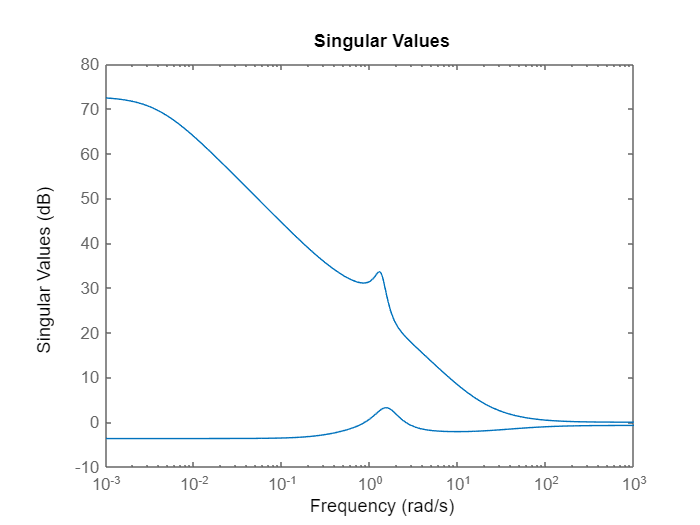

K = Kopt
%BF2

[A, B, C, D] = linmod('BF2');
Gbf2 = ss(A,B,C,D);

mg_mod = 0.6576

Gbf2.u = {'\beta_{initiale}', '\Phi_{initiale}','\beta_{consigne}','\Phi_{consigne}'};          
Gbf2.y = {'\beta', '\Phi'};


K =
 
  D = 
            u1       u2       u3       u4       u5       u6
   y1    26.62    21.25    1.044   -40.28   -38.84   -19.19
   y2  0.02801    -3.02   -10.52    6.005     8.09    2.301
 
Name: Control
Static gain.



figure
impulse(G(1:2,1:2),10); grid on; hold on;
impulse(Gbf2(1:2,1:2), 10); grid on; legend("B0", "BF");hold off;

Comme on pouvait bien s'y attendre, en ayant pas pris en compte le découplage, on a une influence non néglieable de $\beta_{initiale}$ sur $\phi$ 

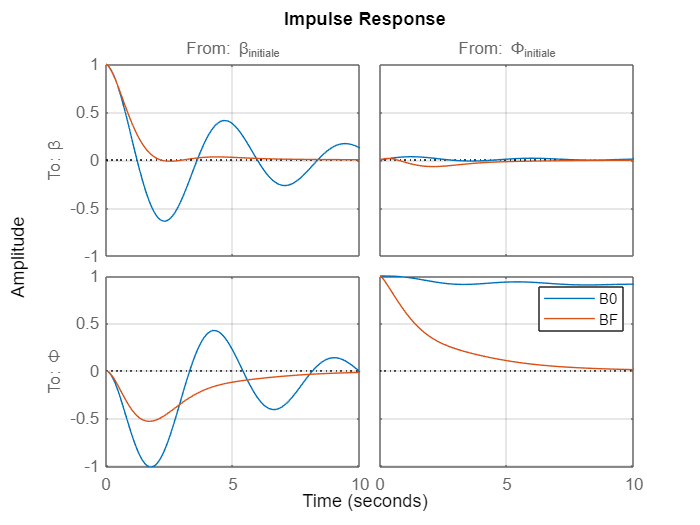

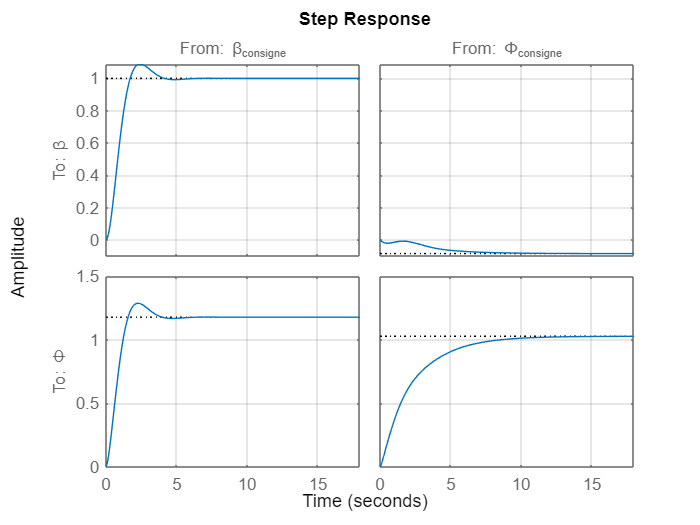

figure
step(Gbf2(1:2,3:4)); grid on; 

En réponse à une échellon, on se retrouve avec un couplage de $\phi$ (l'angle de roulis) à $\beta_{consigne}$ ( la consigne d'angle de dérapage) 